kvarn = imread('kvarn.tif');
kvarn = double(kvarn)/255;

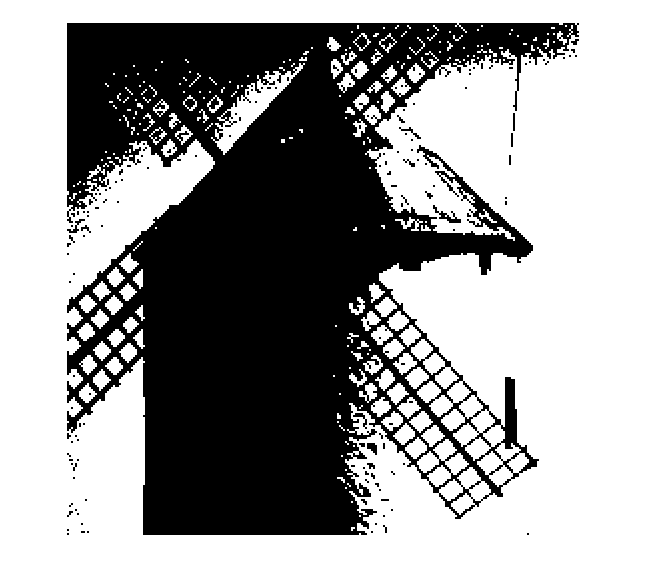

b11 = kvarn>0.5;
imshow(b11);

imwrite(b11,'b11.tif','Resolution',150);

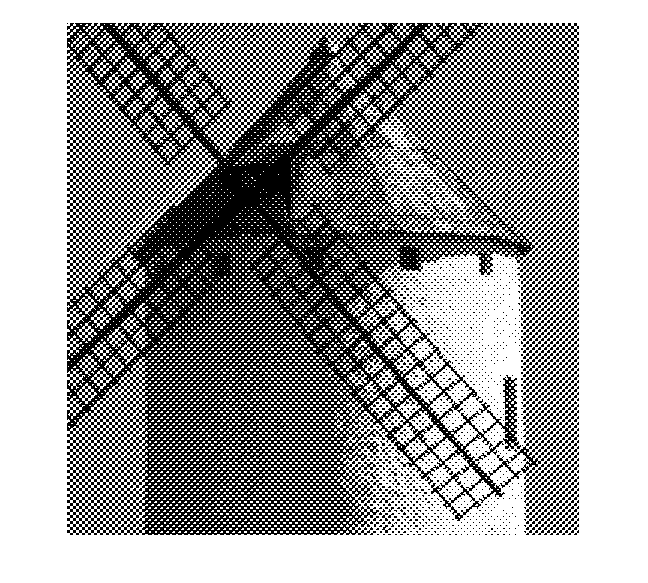

troskelMatris = load('troskelmatriser.mat');
tr1 = double(troskelMatris.tr1)/19;
b12_tr1 = troskel(kvarn,tr1);
imwrite(b12_tr1,'b12_tr1.tif','resolution',150);
tr2 = double(troskelMatris.tr2)/33;
b12_tr2 = troskel(kvarn,tr2);
imwrite(b12_tr2,'b12_tr2.tif','Resolution',150);
imshow(b12_tr1);

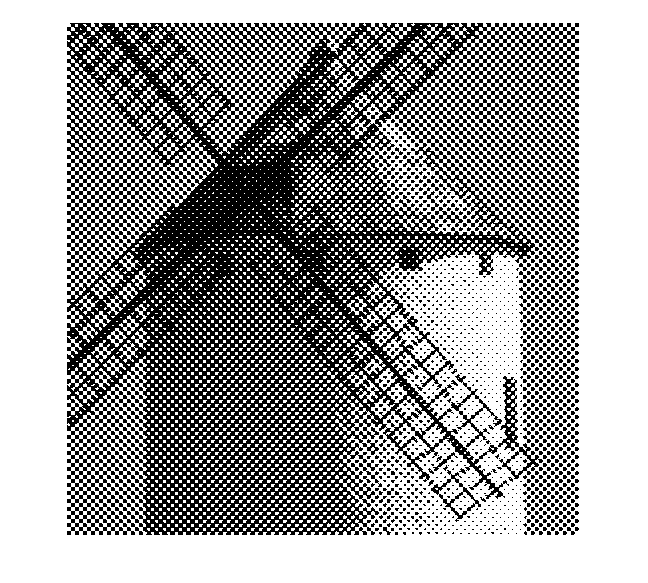

imshow(b12_tr2);

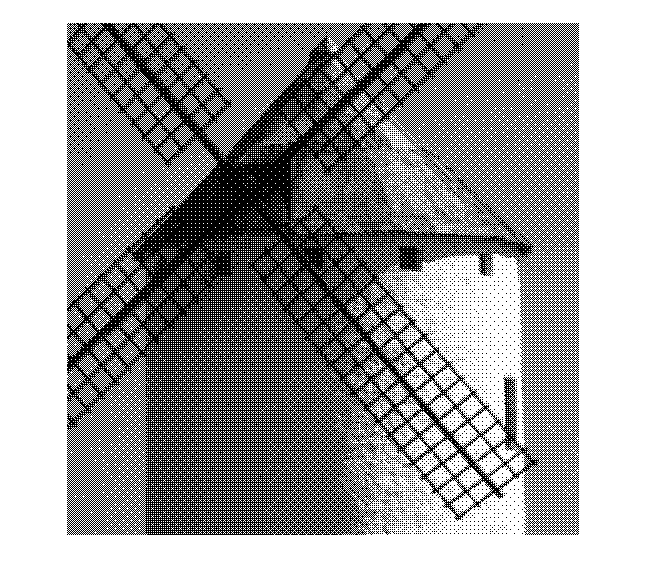

tr3 = double(troskelMatris.tr3)/33;
b13 = troskel(kvarn,tr3);
imwrite(b13,'b13.tif','Resolution',150);
imshow(b13);

linje = [1 2 3 4; 5 6 7 8 ; 9 10 11 12 ;13 14 15 16];
linje = double(linje)/17;
spiral = [7 8 9 10; 6 1 2 11; 5 4 3 12; 16 15 14 13];
spiral = double(spiral)/17;
kvarn_linje = troskel(kvarn,linje);
imwrite(kvarn_linje,'kvarn_linje.tif','Resolution',150);
kvarn_spiral = troskel(kvarn,spiral);
imwrite(kvarn_spiral,'kvarn_sprial.tif','Resolution',150);

b21 = tabellrast(kvarn);
imwrite(b21,'b21.tif','Resolution',150);

b22 = tabellrast2(kvarn);
imwrite(b22,'b22.tif','Resolution',150);

b24 = tabellrast3(kvarn);
imwrite(b24,'b24.tif','Resolution',150);

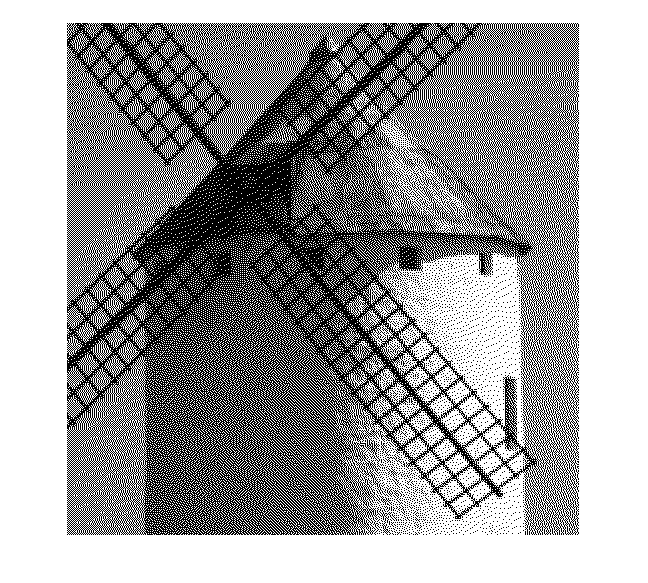

b31 = errordif(kvarn,[0 0 7; 3 5 1]/16);
imwrite(b31,'b31.tif','resolution',150);
imshow(b31)

b32 = errordif(kvarn,[0 0 0 7 5; 3 5 7 5 3; 1 3 5 3 1]/48);
imwrite(b32,'b32.tif','resolution',150);

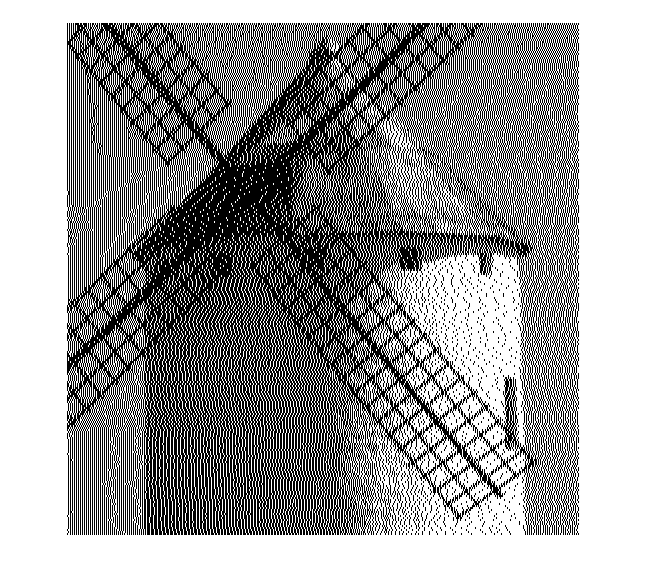

filt_1 = [0 0 1; 0 0 0];
b34a = errordif(kvarn, filt_1);
imwrite(b34a, 'b34a.tif', 'Resolution', 150);
imshow(b34a)

filt_2 = [0 0 1; 0 1 0]/2;
b34b = errordif(kvarn,filt_2);
imwrite(b34b,'b34b.tif','Resolution',150);

brus = rand(512);
brus = brus - 0.5;
brus = brus.*0.3;
damn = kvarn + brus;
b36 = errordif(damn, [0 0 7; 3 5 1]/16);
imwrite(b36,'b36.tif','Resolution',150);

b40 = imcdp(kvarn);

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
95% done
----
here9
here15
here10
here8
here7
here17
here6
here5
here3
here4
here18
here16
here11
here2
here12
here1


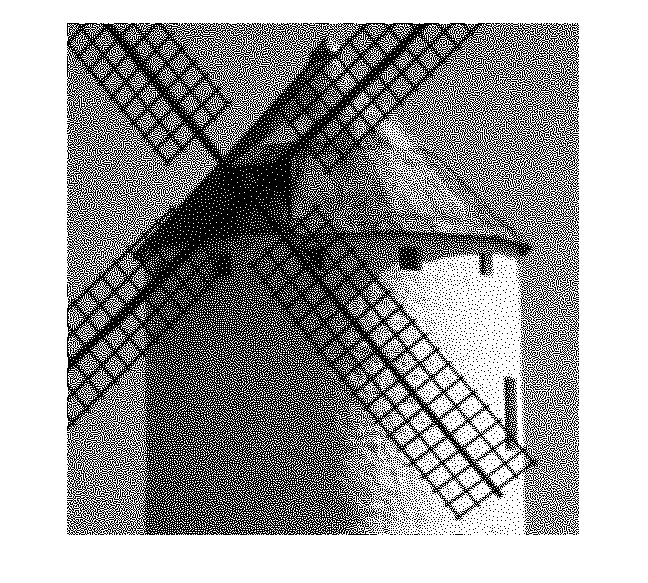

imwrite(b40,'b40.tif','Resolution',150);
imshow(b40);

b51a = kvarn - b11;
a = mysnr(kvarn,b51a)

a = 2.5915

b51b = kvarn - b31;
b = mysnr(kvarn,b51b)

b = 0.8801

b51c = kvarn - b40;
c = mysnr(kvarn, b51c)

c = 0.8069

snr_filter(kvarn,b51a)

ans = 2.9988

snr_filter(kvarn,b51b)

ans = 13.9621

snr_filter(kvarn,b51c)

ans = 12.0248

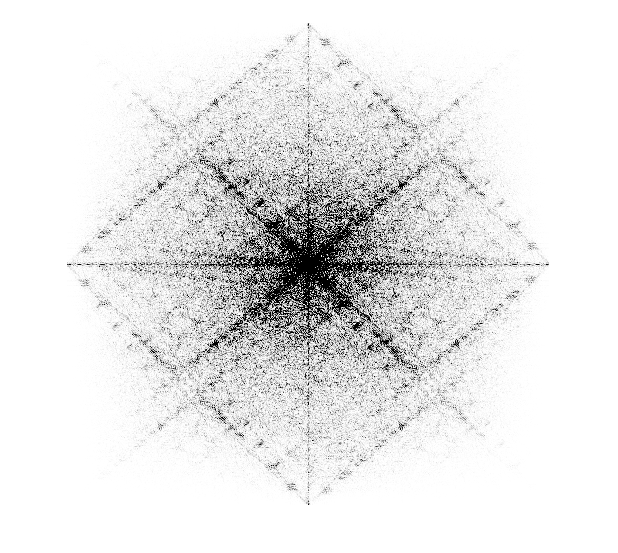

imwrite( QNS(kvarn, b11), 'b53a.tif',"Resolution",150);

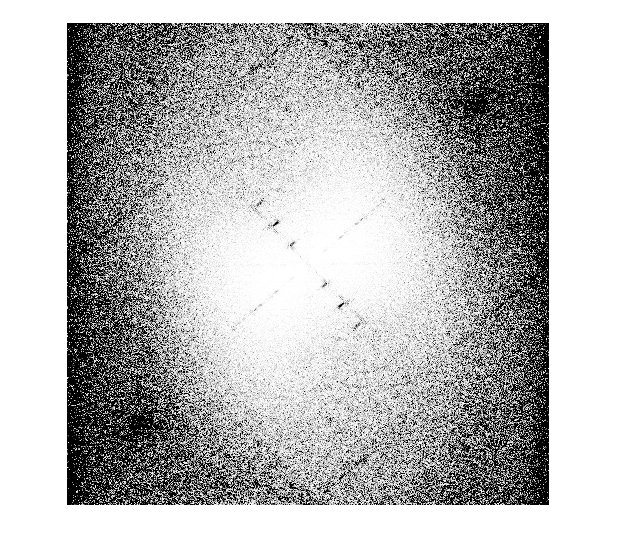

imwrite( QNS(kvarn,b31), 'b53b.tif',"Resolution",150);

imwrite( QNS(kvarn,b40),'b53c.tif',"Resolution",150);

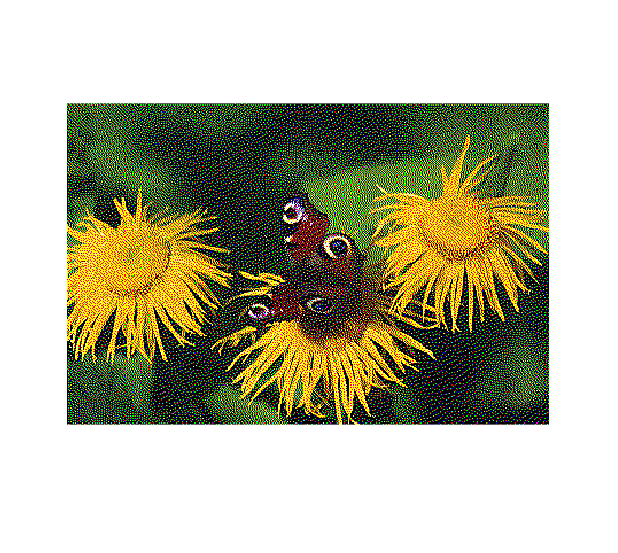

errordif succes


but = imread('Butterfly.tif');
music = imread('musicians.tif');
fargraster(but, 'errordif');

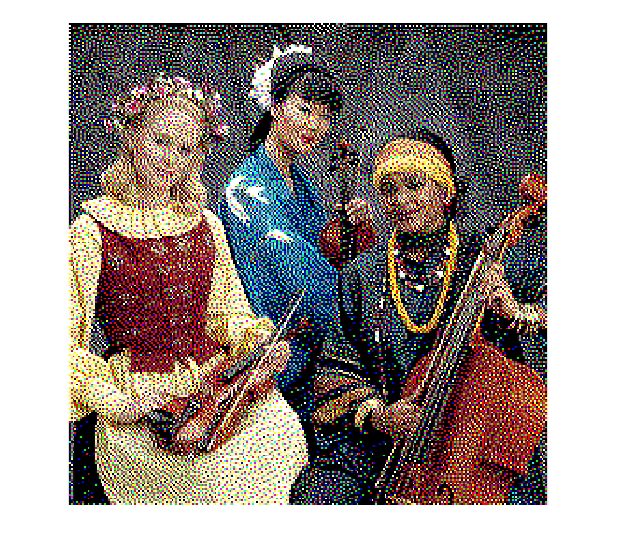

errordif succes


fargraster(music,'errordif');

imcdp
----------
23% done
----
47% done
----
here14
here14
70% done
----
here13
here12
94% done
----
here11
here7
here8
here9
here16
here18
here4
here15
here5
here6
here2
here17
here10
here3
here1
imcdp
----------
here14
24% done
----
here16
48% done
----
48% done
----
here14
here12
here13
72% done
----
here11
96% done
----
here10
here8
here9
here7
here6
here5
here4
here3
here18
here2
here15
here1
here17
imcdp
----------
here15
here16
here17
here3
here6
here4
here14
here8
88% done
----
here9
here7
here14
here10
here11
here13
here12
here5
here2
here18
here1


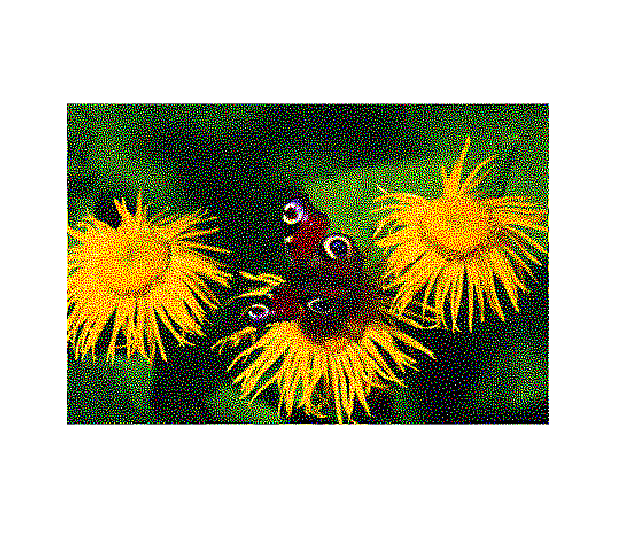

imcdp succes


fargraster(but,'imcdp');

imcdp
----------
37% done
----
74% done
----
here1
here16
here9
here15
here8
here17
here5
here10
here4
here3
here6
here18
here11
here7
here12
here2
here14
here14
here13
imcdp
----------
44% done
----
here1
here15
88% done
----
here14
here9
here17
here4
here18
here8
here10
here7
here6
here3
here11
here2
here5
here12
here16
here14
here13
imcdp
----------
here14
here1
here16
50% done
----
50% done
----
here15
here17
here14
here18
here9
here8
here3
here7
here5
here10
100% done
----
here6
here4
here11
here12
here2
here13


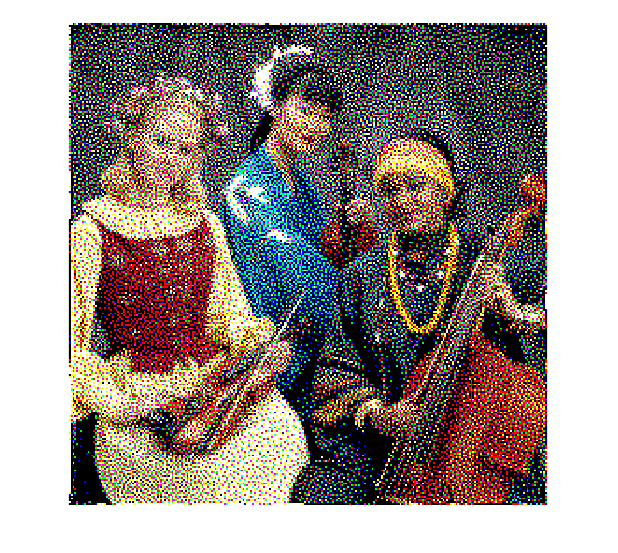

imcdp succes


fargraster(music,'imcdp');

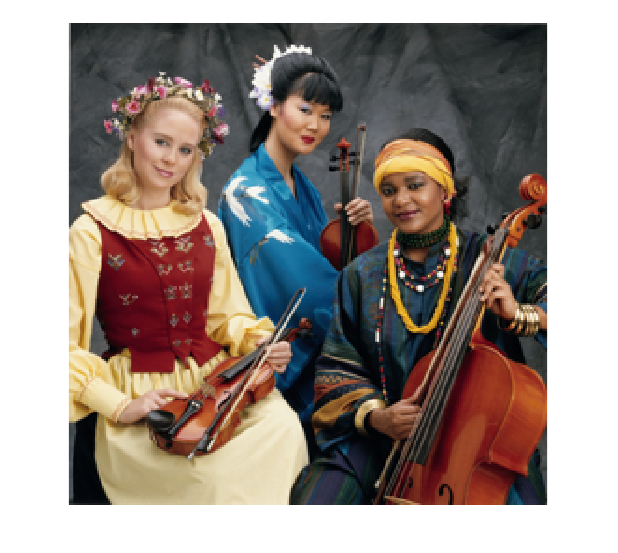

imshow(music);

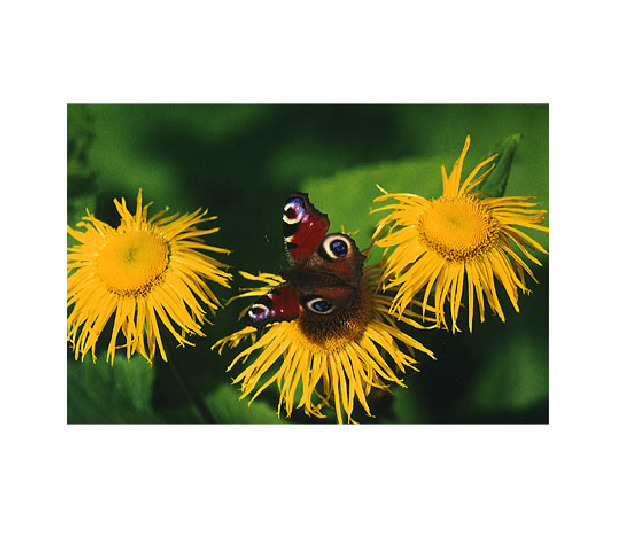

imshow(but);

yeey = imread('Butterfly.tif');
whos("yeey");

  Name        Size                Bytes  Class    Attributes

  yeey      280x420x3            352800  uint8              



errordif succes


lala = fargraster(but, 'errordif');

whos("lala");

  Name        Size                 Bytes  Class     Attributes

  lala      280x420x3            2822400  double              

